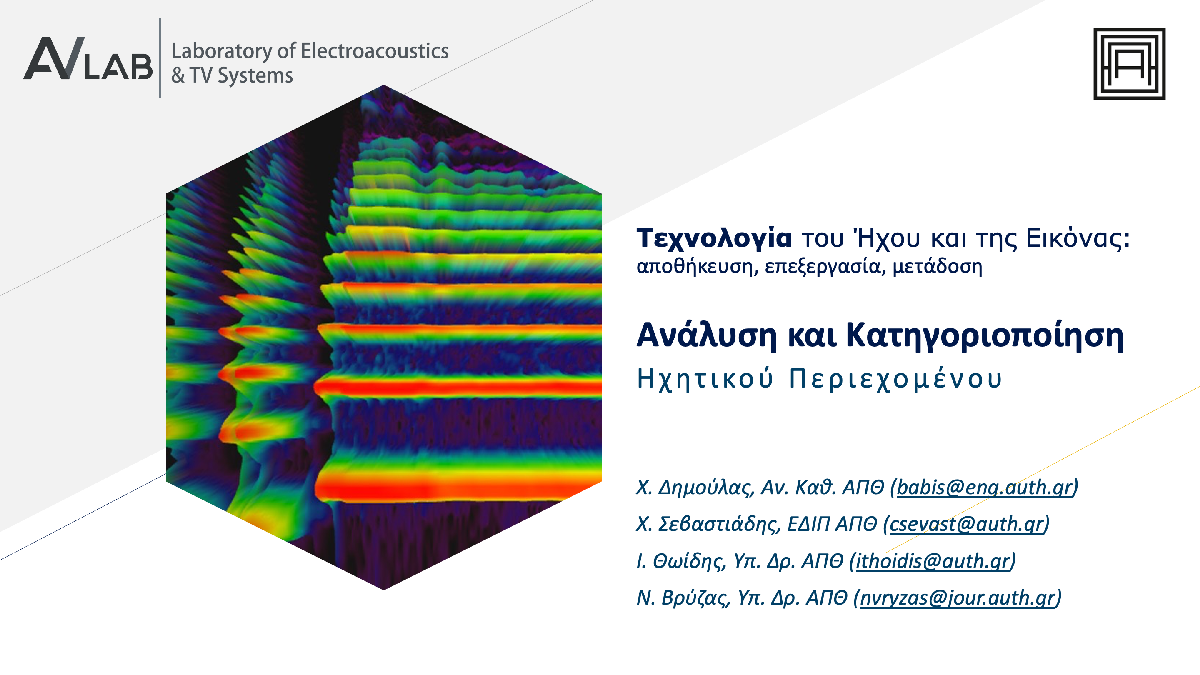

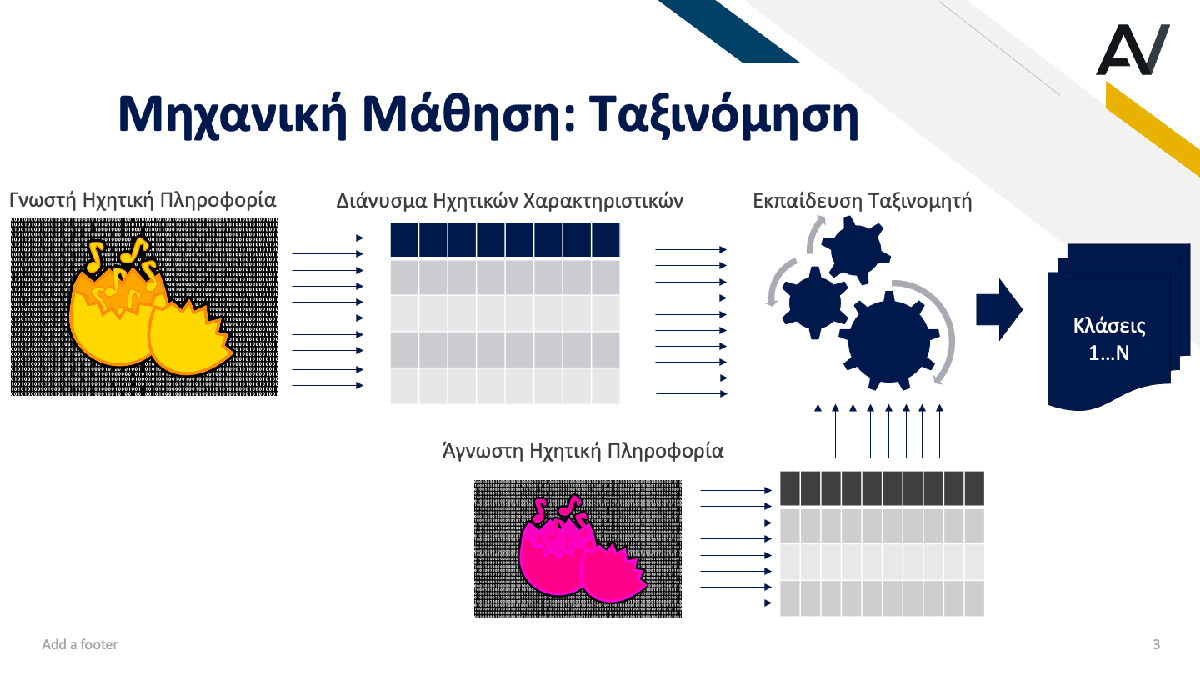

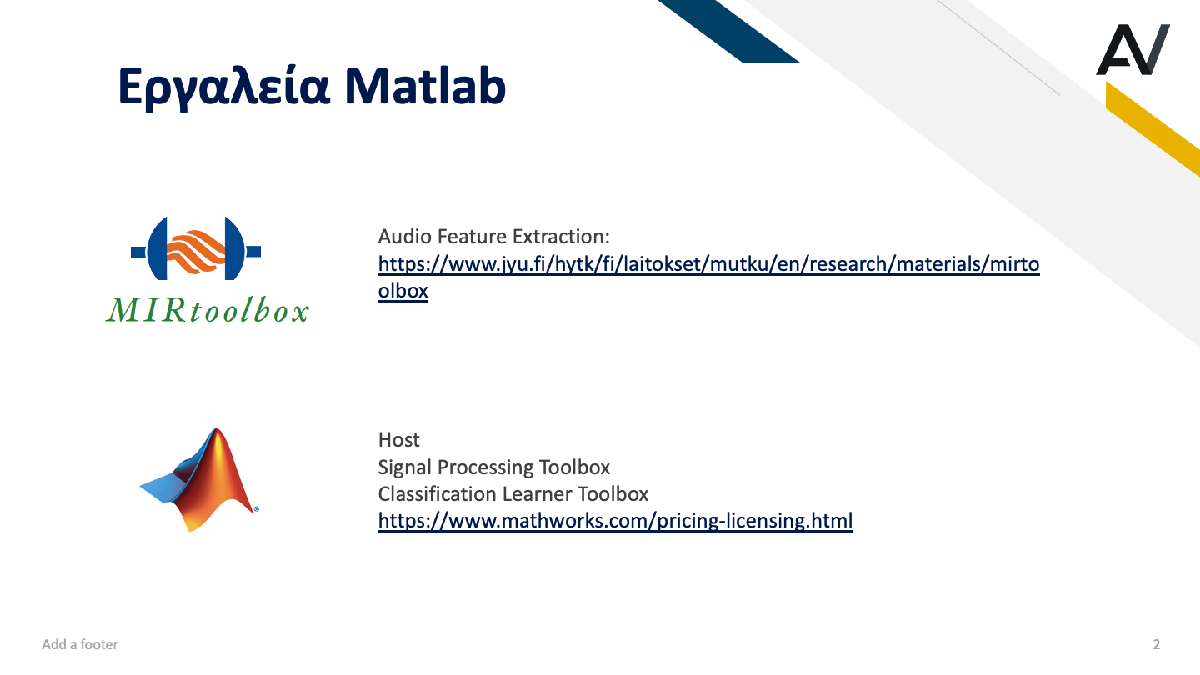

click here -> [MIRtoolbox](https://www.jyu.fi/hytk/fi/laitokset/mutku/en/research/materials/mirtoolbox )

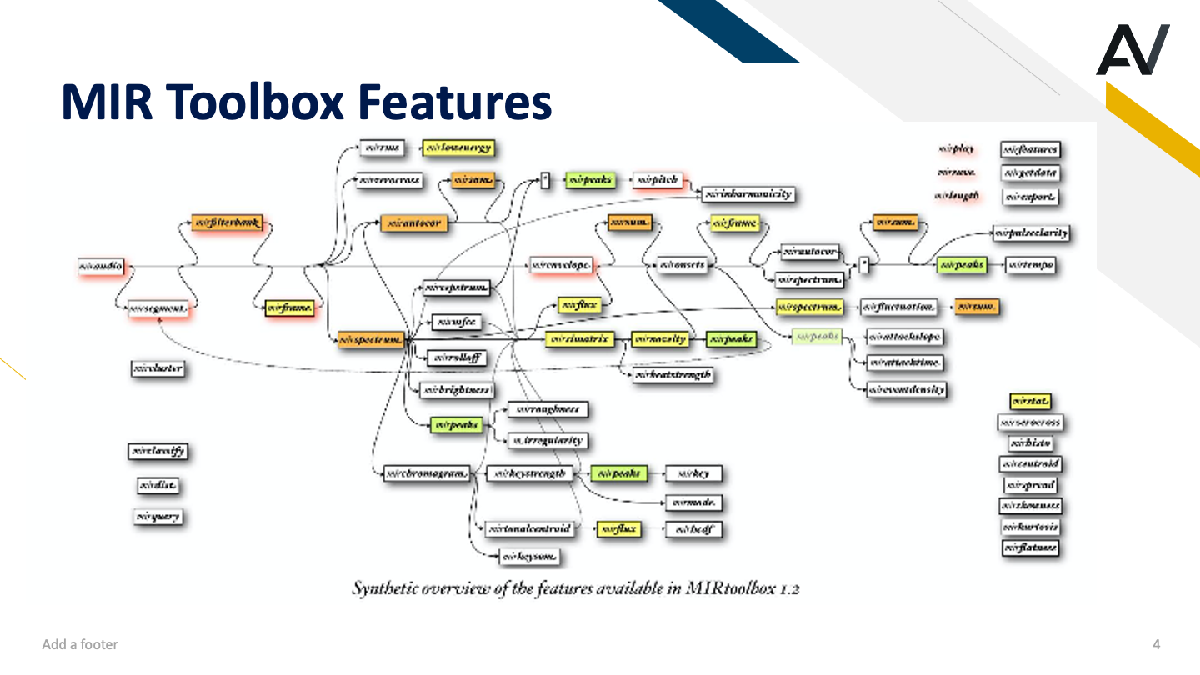

Load Audio Toolbox

fullfile(matlabroot,'toolbox','audio','samples');

file = 'monoGMM.wav';
% native loading of audio files
[audio, fs] = audioread(file)

fs = 44100

% MIRToolbox load audio file
audio_mir = mirgetdata(miraudio(file))

Computing miraudio related to monoGMM.wav...
Computing mirsum related to monoGMM.wav...
Elapsed time is 1.372457 seconds.


[audio_stereo, fs] = audioread('stereoGMM.wav');
sound(audio_stereo, fs);
subplot(2,1,1)
plot(audio_stereo(:, 1));
subplot(2,1,2)
plot(audio_stereo(:, 2));
% convert to mono one way or another
audio_mono = sum(audio_stereo, 2)/2;
% or
audio_mono = audio_stereo(:,1);

% play sound in a different sampling rate
sound(audio, 22050);

% Record and change parameters
fs = 44100;
bit_depth = 8;
recObj = audiorecorder(fs, bit_depth, 1);
disp('Start speaking.');

Start speaking.


recordblocking(recObj, 5);
disp('End of Recording.');

End of Recording.


y = getaudiodata(recObj);
sound(y, fs);

Frequency Spectrum - Audio Effects - EQ and Compression

file = 'trumpet.wav';
[audio, fs] = audioread(file);
s = mirspectrum(file)

Computing miraudio related to trumpet.wav...
Computing mirsum related to trumpet.wav...
Computing mirspectrum related to trumpet.wav...
Elapsed time is 2.236500 seconds.
 
s is the Spectrum related to trumpet.wav, of sampling rate 11025 Hz.


Its content is displayed in Figure 2.
 


mPEQ = multibandParametricEQ('NumEQBands', 3,...
                        'Frequencies',[300,1200,5000], ...
                        'QualityFactors', [1.6, 1.6, 1.6], ...
                        'PeakGains', [-20, -5, 5]);
visualize(mPEQ);

audioOut = mPEQ(audio);
sound(audio, fs);
pause;
sound(audioOut, fs);

s1 = mirspectrum(miraudio(audio, fs));
s2 = mirspectrum(miraudio(audioOut, fs));
figure;
plot(mirgetdata(s1));
hold on;
plot(mirgetdata(s2));

figure
spectrogram(audio,round(fs*0.1),round(fs*0.04),round(fs*0.05),fs,'yaxis','power')
view([-58 33])

Dynamic Range Compressor

drc = compressor(-15, 2, ...
    'SampleRate',fs, ...
    'AttackTime',0.050, ...
    'ReleaseTime',0.200, ...
    'MakeUpGainMode','Property');

visualize(drc);
x = [ones(fs,1);0.1*ones(fs,1)];
[y,g] = drc(x);
%sound(x, fs);
%pause;
%sound(y, fs);

figure
subplot(211)
t = (1/fs) * (0: size(y,1)-1)';
plot(t,x);
hold on
grid on
plot(t,y,'r')
ylabel('Amplitude')
legend('Input','Compressed Output')

subplot(212)
plot(t,g)
grid on
legend('Compressor gain (dB)')
xlabel('Time (sec)')
ylabel('Gain (dB)')

figure;
[x,g] = drc(audio);
spectrogram(x,round(fs*0.1),round(fs*0.04),round(fs*0.05),fs,'yaxis','power')
view([-58 33])

Framing and Spectrograms

file ='trumpet.wav';
mirplay(file);
audio_framed = mirframe(file, 'Length', 0.050, 'Hop', 0.5)

file ='trumpet.wav';
s = mirspectrum(file, 'Frame', 0.01, 0.5, 'Window', 'hann')

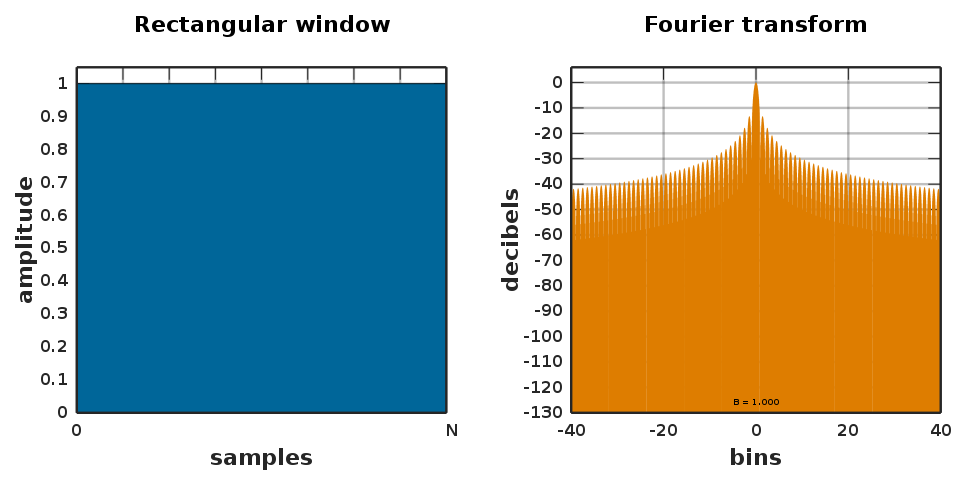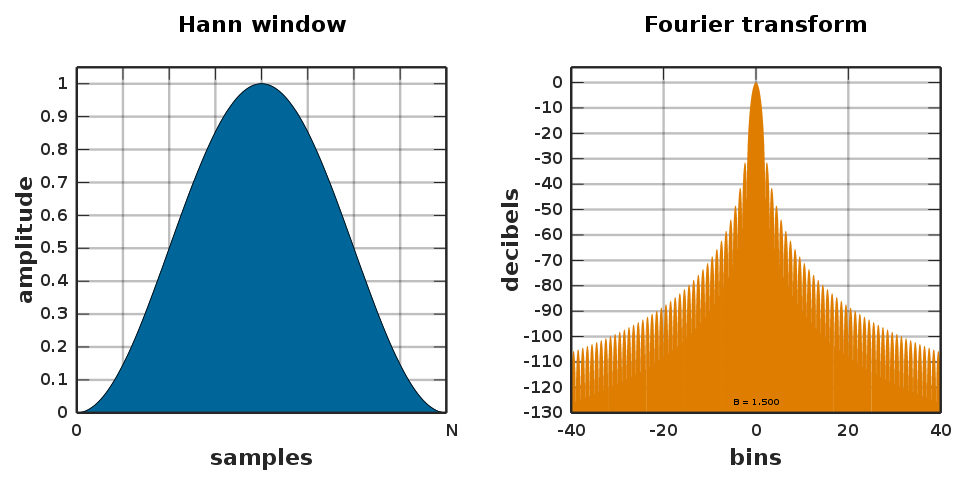

Audio Features

file = 'guitar.wav';
mirplay(file);
a = mirframe(file, 'Length', 0.1, 'Hop', 0.5);
s = mirspectrum(s);
z = mirzerocross(a)
c = mircentroid(s)
r = mirrolloff(s)
i = mirbrightness(s)
at = mironsets(file,'Attacks')
mirroughness(s) 
mirchromagram(a)

file = 'czardas.wav';
[audio, fs] = audioread(file);
sound(audio, fs);
[k kc ks] = mirkey(file)

SMO - Entropy Distribution

fs = 8000;
[speech,speechFs] = audioread('Counting-16-44p1-mono-15secs.wav'); 
speech = resample(speech,fs,speechFs);
speech = speech./max(speech);
[music,musicFs] = audioread('RockGuitar-16-96-stereo-72secs.flac'); 
music = sum(music,2)/2;
music = resample(music,fs,musicFs);
music = music./max(music);
[background,backgroundFs] = audioread('Ambiance-16-44p1-mono-12secs.wav'); 
background = resample(background,fs,backgroundFs);
background = background./max(background);

win_length = 0.05;
overlap = 0.5;
speechFramed = mirframe(speech, 'Length', win_length, 'Hop', overlap);
musicFramed = mirframe(music, 'Length', win_length, 'Hop', overlap);
backgroundFramed = mirframe(background, 'Length', win_length, 'Hop', overlap);

speechEntropy = mirgetdata(mirentropy(speechFramed))';
musicEntropy = mirgetdata(mirentropy(musicFramed))';
backgroundEntropy = mirgetdata(mirentropy(backgroundFramed))';
figure
h1 = histogram(speechEntropy);
hold on
h2 = histogram(musicEntropy);
h3 = histogram(backgroundEntropy);
h1.Normalization = 'probability'; h2.Normalization = 'probability'; h3.Normalization = 'probability'; h1.BinWidth = 0.01;
h2.BinWidth = 0.01;
h3.BinWidth = 0.01;
title('Spectral Entropy') 
legend('Speech','Music','Background','Location',"northwest") 
xlabel('Entropy')
ylabel('Probability')
hold off

Filterbank analysis

file ='trumpet.wav';
fs = cell2mat(get(s,'Sampling'));
audio_filterbank = mirfilterbank(file, 'Gammatone')
audio_filterbank_data = mirgetdata(audio_filterbank);
sound(sum(audio_filterbank_data(:, :, 1:3), 3), fs);

file = 'FA01_01.wav';
[audio, fs] = audioread(file);
sound(audio, fs);
audio_filterbank = mirfilterbank(file, 'Gammatone')
e = mirenvelope(audio_filterbank)
s = mirspectrum(file, 'Frame', 0.01, 0.5, 'Window', 'hann')
mirpeaks(s)
ylim([50, 2000]);

Using LPC algorithm to extract useful information about speech characteristics and resynthesize the degraded speech 

inpfilenm = 's2ofwb.wav';
[x, fs] =audioread(inpfilenm);
M=10;
[aCoeff, pitch_plot, voiced, gain] = f_ENCODER(x, fs, M);  %pitch_plot is pitch periods

figure
subplot(3,1,1), plot(pitch_plot), title(['Pitch']);
subplot(3,1,2), plot(voiced), title(['Voiced Segment']);
subplot(3,1,3), plot(gain), title(['Gain']);

synth_speech = f_DECODER(aCoeff, pitch_plot, voiced, gain);

sound(x, fs);
pause(size(x,1)/fs +1);
sound(synth_speech, fs);

figure;
subplot(2,1,1), plot(x); 
title(['Original signal']); 
subplot(2,1,2), plot(synth_speech); 
title(['synthesized speech of using LPC']);

filenames_guitar = dir('train/acoustic guitar/*.wav');
filenames_drums = dir('train/drums/*.wav');

mirplay(filenames_guitar(4).name);
mirplay(filenames_drums(20).name);

guitar = [];
for i=1:2%size(filenames_guitar,1)
    features = extraction(filenames_guitar(i).name);
    class = 'guitar';
    guitar = [guitar; array2table(features),{class}];
end
drums=[]
for i=1:2%size(filenames_drums,1)
    features = extraction(filenames_drums(i).name);
    class = 'drums';
    drums = [drums; array2table(features),{class}];
end
traintable = [guitar; drums];
predictorNames = {'AF1', 'AF2', 'AF3', 'AF4', 'AF5', 'AF6', 'AF7', 'AF8', 'AF9', 'AF10', 'AF11', 'AF12', 'AF13', 'AF14', 'AF15', 'AF16', 'AF17', 'AF18', 'AF19', 'AF20', 'AF21', 'AF22', 'AF23', 'AF24', 'AF25', 'AF26', 'AF27', 'AF28', 'AF29', 'AF30', 'AF31', 'AF32', 'AF33', 'AF34', 'AF35', 'AF36', 'AF37','class'};
traintable.Properties.VariableNames = predictorNames;

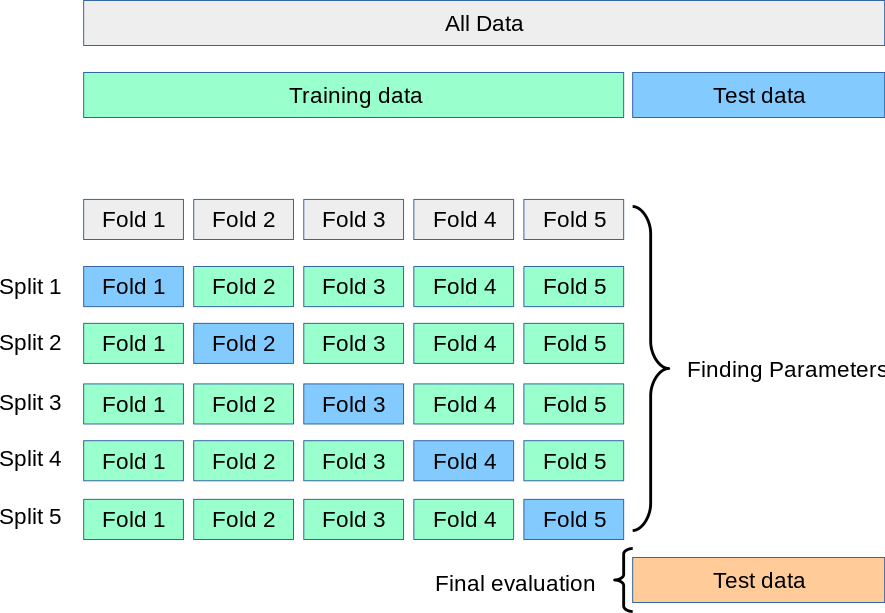

predictorNames = {'AF1', 'AF2', 'AF3', 'AF4', 'AF5', 'AF6', 'AF7', 'AF8', 'AF9', 'AF10', 'AF11', 'AF12', 'AF13', 'AF14', 'AF15', 'AF16', 'AF17', 'AF18', 'AF19', 'AF20', 'AF21', 'AF22', 'AF23', 'AF24', 'AF25', 'AF26', 'AF27', 'AF28', 'AF29', 'AF30', 'AF31', 'AF32', 'AF33', 'AF34', 'AF35', 'AF36', 'AF37','class'};
x_train = traintable(:,predictorNames(1:37));
y_train = traintable.class;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

% Train a classifier
model = fitcknn(x_train,y_train,'NumNeighbors',4,'ClassNames', categorical({'drums'; 'guitar'}));
cv_model = crossval(model, 'KFold', 5);
train_loss = kfoldLoss(cv_model)

figure
gscatter(table2array(x_train(:,3)),table2array(x_train(:,2)),y_train(:,1))

% Evaluate 
filenames_test = dir('test/*.wav');
testset=[];
for i=1:size(filenames_test,1)
    features = extraction(filenames_test(i).name);
    testset = [testset; array2table(features)];
end

% Evaluate model using the test set
predictorNames = {'AF1', 'AF2', 'AF3', 'AF4', 'AF5', 'AF6', 'AF7', 'AF8', 'AF9', 'AF10', 'AF11', 'AF12', 'AF13', 'AF14', 'AF15', 'AF16', 'AF17', 'AF18', 'AF19', 'AF20', 'AF21', 'AF22', 'AF23', 'AF24', 'AF25', 'AF26', 'AF27', 'AF28', 'AF29', 'AF30', 'AF31', 'AF32', 'AF33', 'AF34', 'AF35', 'AF36', 'AF37'};
testset.Properties.VariableNames = predictorNames
y_test = guess;
y_hat = trainedModel1.predictFcn(testset)

y_hat = 18×1 categorical array
     guitar 
     guitar 
     guitar 
     guitar 
     guitar 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 
     drums 


err = loss(trainedModel1, testset, y_test)

Undefined function 'loss' for input arguments of type 'table'.

Record audio and model inference

recObj = audiorecorder(44100, 16, 1);
disp('guitar or drums');

guitar or drums


recordblocking(recObj, 5);
disp('Recording stopped.');

Recording stopped.


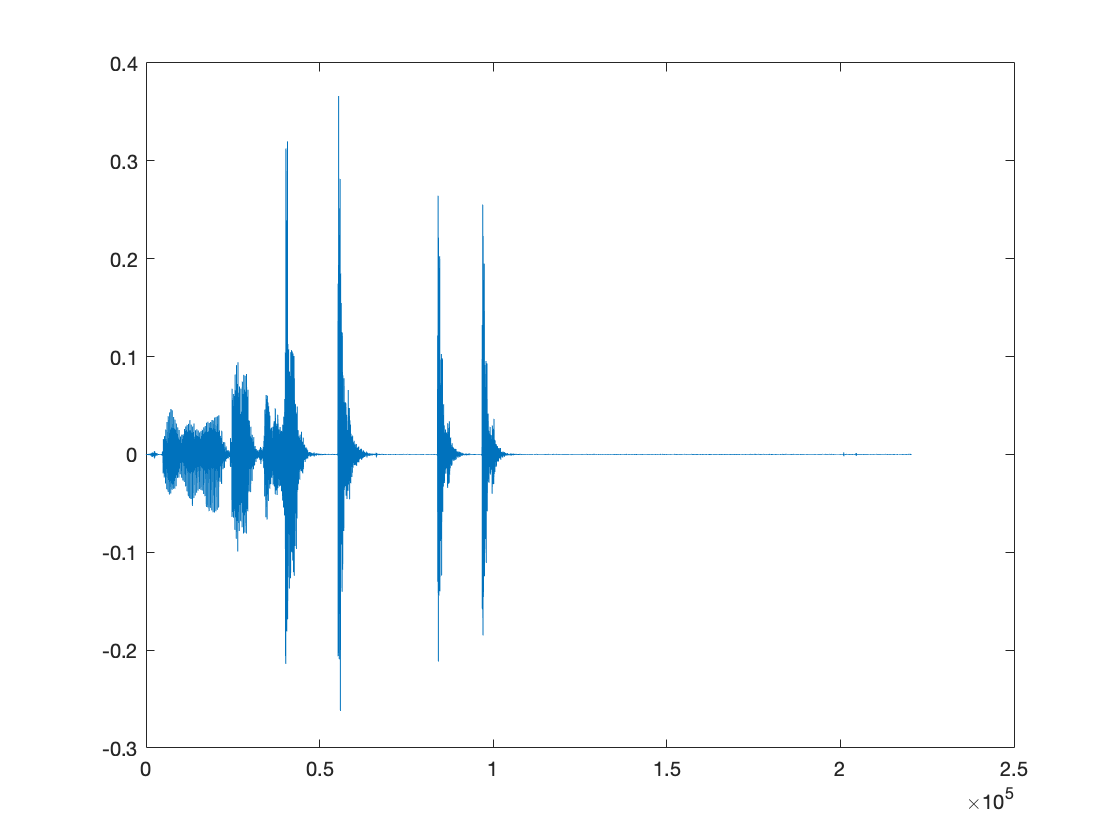

play(recObj);
wave = getaudiodata(recObj);
plot(wave);

wave_mir = miraudio(wave, 44100);
features = array2table(extraction(wave_mir));

Computing mirpeaks related to wave...


Computing mirrms related to wave...
Computing mirrms related to wave...
Computing mirlowenergy related to wave...
Computing mirspectrum related to wave...
Computing mirenvelope related to wave...
Computing mironsets related to wave...
Computing mirsum related to wave...
Computing mirenvelope related to wave...
Computing mirpeaks related to wave...
Computing mireventdensity related to wave...
Computing mirpeaks related to wave...
Computing mirzerocross related to wave...
Computing mirspectrum related to wave...
Computing mirrolloff related to wave...
Computing mirrms related to wave...
Computing mirspectrum related to wave...
Computing mirrolloff related to wave...
Computing mirrms related to wave...
Computing mirspectrum related to wave...
Computing mirrolloff related to wave...
Computing mirrms related to wave...
Computing mirspectrum related to wave...
Computing mirrolloff related to wave...
Computing mirrms related to wave...
Computing mirspectrum related to wave...
Computing mirrol

predictorNames = {'AF1', 'AF2', 'AF3', 'AF4', 'AF5', 'AF6', 'AF7', 'AF8', 'AF9', 'AF10', 'AF11', 'AF12', 'AF13', 'AF14', 'AF15', 'AF16', 'AF17', 'AF18', 'AF19', 'AF20', 'AF21', 'AF22', 'AF23', 'AF24', 'AF25', 'AF26', 'AF27', 'AF28', 'AF29', 'AF30', 'AF31', 'AF32', 'AF33', 'AF34', 'AF35', 'AF36', 'AF37'};
features.Properties.VariableNames = predictorNames

trainedModel1.predictFcn(features)

ans = categorical
     drums 
